# Metodi di interpolazione

## Introduzione

Quando parliamo di interpolazione ci stiamo riferendo alla creazione di polinomi che passano attraverso una serie di punti di coordinate e all'**approssimazione**. Mettiamo caso che una stazione meteo voglia approssimare un polinomio passante per una serie di misurazioni, essere le temperature registrate annualmente. La curva che rappresenta la variazione delle temperature sarà un **polinomio interpolatore** $p\left(x\right)$ della forma


$$a_n x^n a_{n-1} x^{n-1} +\cdots +a_2 x^2 +a_1 x+a_0$$


con $a_n \cdots a_0$ i **coefficienti** e con $x^n \cdots 1$ l'**incognita**. Vediamo un esempio d'interpolazione usando una serie di dati di coordinate, predisposte tramite il comando `rand`.

x = rand(1, 10);
y = rand(1, size(x,2));

n = size(x,2);

X = linspace(min(x), max(x), 100); % intervallo valutazione polinomio

figure; hold on; grid on
xlim([min(x) max(x)])
xlabel('x'); ylabel('y')
title('Polinomio interpolatore')
plot(x, y, 'r*', 'DisplayName', 'Nodes')
legend

Per **trovare i coefficienti del polinomio interpolatore**, usiamo il comando `polyfit`. Il grado del polinomio interpolatore passante per $n$ punti è $n-1$.

p = polyfit(x, y, n-1); % calcolo coefficienti

Per **valutare il polinomio usando i coefficienti** salvati, usiamo il comando `polyval`. Quando diciamo "valutare il polinomio interpolatore", stiamo dicendo di calcolare i valori del polinomio passante per i punti in un intervallo che li comprende.

Y = polyval(p, X); % valutazione polinomio

Stampiamo il polinomio interpolatore.

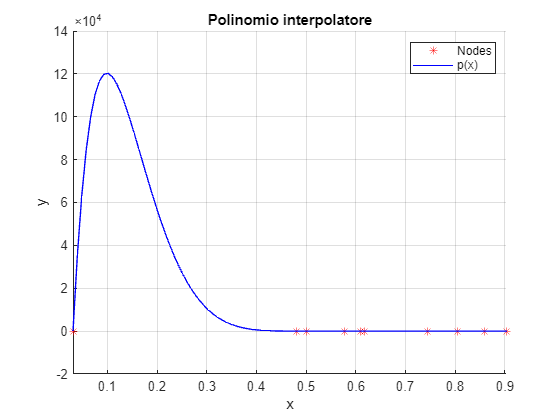

plot(X, Y, 'b-', 'DisplayName', 'p(x)')

## Algoritmi

Un algoritmo d'interpolazione è più o meno preciso a seconda di criteri da noi stabiliti. Per esempio, immaginiamo di volere approssimare la funzione `sin`. Tralasciando il fatto che questo argomento sia famoso, potremmo pensare di usare un polinomio interpolatore di $n$ punti anzichè valutare la funzione.

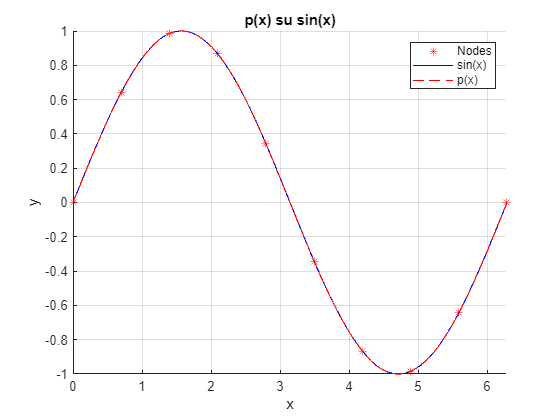

f = @(x) sin(x);

x = linspace(0, 2*pi, 10); % nodi equispaziati

figure; hold on; grid on
xlabel('x'); ylabel('y')
xlim([min(x) max(x)])
title('p(x) su sin(x)')
plot(x, f(x), 'r*', 'DisplayName', 'Nodes')

X = linspace(min(x), max(x), 1000); % intervallo valutazione polinomio

plot(X, f(X), 'b-', 'DisplayName', 'sin(x)')

p = polyfit(x, f(x), 9);
Y = polyval(p, X);

plot(X, Y, 'r--', 'DisplayName', 'p(x)')
legend

### Metodo di Lagrange

Per trovare il polinomio interpolante $p\left(x\right)$ il metodo di Lagrange fa uso delle proprietà dei polinomi fondamentali di Lagrange $l_i \left(x\right)$. Il polinomio lagrangiano vale 1 se $i=j$ e 0 se $i\not= j$, dove


$$l_i \left(x\right)=\prod_{j=0,j\not= i}^n \frac{x-x_j }{x_i -x_j }\;\;\;\;\;\;\;\;n=\textrm{grado}\;\textrm{del}\;\textrm{polinomio}$$


Il polinomio interpolante i punti di ordinate $y_i$ è uguale a


$$p\left(x\right)=\sum_{i=0}^n y_i l_i \left(x\right)\;\;\;\;\;\;\;\;n=\textrm{grado}\;\textrm{del}\;\textrm{polinomio}$$


Il grosso vantaggio di questo metodo deriva dalla proprietà dei polinomi fondamentali che portano a valutare i termini a 0. Lo svantaggio del metodo è che al cambiare del grado di precisione tutte le operazioni devono essere eseguite nuovamente, siccome i termini dipendono dal grado.

### Metodo delle differenze divise di Newton

Il metodo di Newton di basa sul concetto delle differenze divise. Data una serie di punti $x_i$ e $y_i$, scriviamo che differenze divise come colonne della forma seguente


$$y_n =f\left\lbrack x_n \right\rbrack \cdots f\left\lbrack x_{n-1} ,x_n \right\rbrack \cdots f\left\lbrack x_0 ,\ldots,x_n \right\rbrack$$


dove ogni termine è una differenza divisa. La differenza divisa di ordine $k$ ha la forma seguente


$$f\left\lbrack x_i ,\ldots,x_{i+k} \right\rbrack =\frac{f\left\lbrack x_{i+1} ,\ldots,x_{i+k} \right\rbrack -f\left\lbrack x_i ,\ldots,x_{i+n-1} \right\rbrack }{x_{i+k} -x_i }\;\;\;\;\;\;\;\;i=0,\ldotp \ldotp ,n-k$$


e il polinomio delle differenze divise è di forma


$$p_n \left(x\right)=f\left\lbrack x_0 \right\rbrack +f\left\lbrack x_0 ,x_1 \right\rbrack \left(x-x_0 \right)+\cdots +f\left\lbrack x_0 ,\ldots,x_n \right\rbrack \left(x-x_0 \right)\cdots \left(x-x_{n-1} \right)$$


A differenza del metodo di Lagrange, il metodo di Newton non ricalcola l'intera serie di coefficienti al cambiare del grado del polinomio.

### Matrice di Vandermonde

I **coefficienti di un polinomio interpolatore** possono essere **calcolati** usando la matrice di Vandermonde. Questa matrice permette, a partire da una serie di nodi, di ottenere i coefficienti del polinomio interpolatore $p\left(x\right)$ tramite la risoluzione del sistema lineare $\textrm{Ax}=b$. Il comando `vander` calcola la matrice di Vandermonde $A$ usando un vettore di lunghezza $n$.

- Scelta del numero di nodi interpolanti.

- Scelta intervallo d'interpolazione.

- Calcolo della matrice di Vandermonde sui nodi interpolanti.

- Calcolo dei coefficienti tramite risoluzione sistema lineare.

- Valutazione del polinomio interpolante.

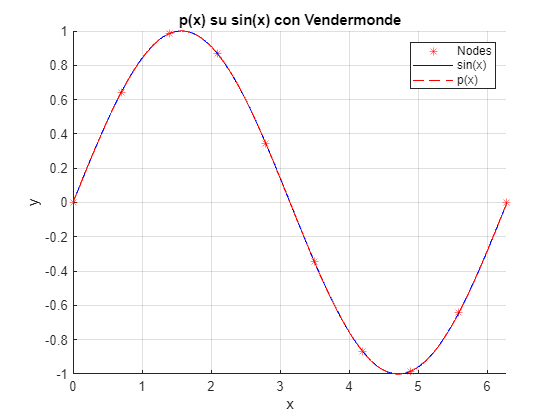

x = linspace(0, 2*pi, 10); % 1

figure; hold on; grid on
xlabel('x'); ylabel('y')
xlim([min(x) max(x)])
title('p(x) su sin(x) con Vendermonde')
plot(x, f(x), 'r*', 'DisplayName', 'Nodes')

X = linspace(min(x), max(x), 1000); % 2

plot(X, f(X), 'b-', 'DisplayName', 'sin(x)')

A = vander(x); % 3
p = A \ f(x)'; %4 % p = polyfit(x, f(x), 9);
Y = polyval(p, X); % 5

plot(X, Y, 'r--', 'DisplayName', 'p(x)')

legend

### Retta di regressione lineare

Una retta di regressione lineare è una retta che cerca di **approssimare** la **variazione di una variabile** al **cambiare di uno scalare**. La retta $y=\textrm{mx}+q$ è descritta dalle seguenti


$$m=\frac{n\sum x_i y_i -\sum x_i \sum y_i }{n\sum x_i^2 -{\sum x_i }^2 }\;\;\;\;\;\;\;\;q=\frac{\sum y_i \sum x_i^2 -\sum x_i \sum x_i y_i }{n\sum x_i^2 -{\sum x_i }^2 }$$


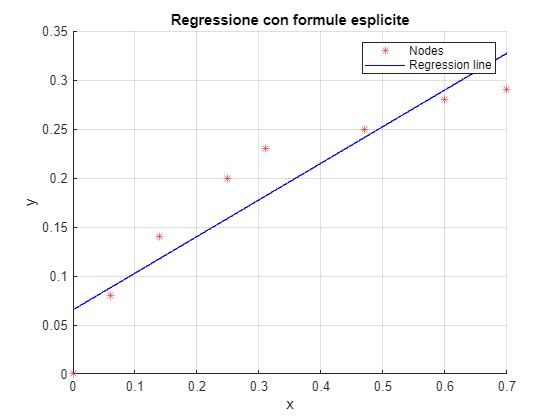

xi = [0.00, 0.06, 0.14, 0.25, 0.31, 0.47, 0.60, 0.70];
yi = [0.00, 0.08, 0.14, 0.20, 0.23, 0.25, 0.28, 0.29];
x = linspace(min(xi), max(xi), 100);
n = length(xi);

figure; hold on; grid on;
xlabel('x'); ylabel('y');
xlim([min(x) max(x)])
title('Regressione con formule esplicite')
plot(xi, yi, 'r*', 'DisplayName', 'Nodes')

den = n*sum(xi.^2) - sum(xi)^2; % Denominatore comune
m = (n*sum(xi.*yi) - sum(xi)*sum(yi)) / den; % Coefficiente angolare
q = (sum(yi)*sum(xi.^2)-sum(xi)*sum(xi.*yi)) / den; % Punto intersezione
y = m*x + q; % Retta di regressione

plot(x, y, 'b-', 'DisplayName', 'Regression line')
legend

Siccome questa retta altro non è che un polinomio interpolante, quindi un $p\left(x\right)$ di grado 1, possiamo usare i comandi `polyfit` e `polyval`.

figure; hold on; grid on;
xlabel('x'); ylabel('y')
xlim([min(x) max(x)])
title('Regressioni con polyfit e polyval')
plot(xi, yi, 'r*', 'DisplayName', 'Nodes')

p = polyfit(xi, yi, 1);
y = polyval(p, x);

plot(x, y, 'b-', 'DisplayName', 'Regression line')
legend

### Parabola di regressione

Similarmente alla retta, la parabola di regressione è una curva che tende ad approssimare gli andamenti facendolo con una curva interpolante quindi un $p\left(x\right)$ di grado 2. Usiamo sempre i comandi `polyfit` e `polyval` per ottenere la curva.

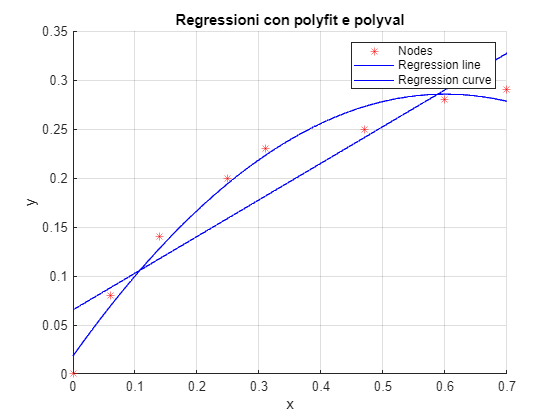

p = polyfit(xi, yi, 2);
Y = polyval(p, X);

plot(X, Y, 'b-', 'DisplayName', 'Regression curve')

## Precisione

Stampare la precisione di un polinomio interpolatore significare trovarne l'**errore sul risultato**. Per calcolare questo errore, usiamo la formula


$$e=|f\left(x\right)-p\left(x\right)|$$


dove $f\left(x\right)$ è il vettore di elementi esatti valutati per la funzione esatta e $p\left(x\right)$ il vettore di elementi valutati dal polinomio interpolante. Quello che otteniamo è un vettori di errori che possiamo stampare.

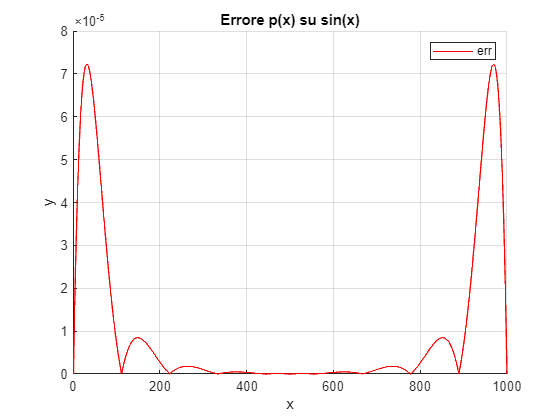

f = @(x) sin(x);

x = linspace(0, 2*pi, 10); % nodi equispaziati
X = linspace(min(x), max(x), 1000); % intervallo valutazione polinomio

p = polyfit(x, f(x), 9);
Y = polyval(p, X);

err = abs(f(X) - Y); % errore sul risultato

figure; hold on; grid on;
xlabel('x'); ylabel('y')
title('Errore p(x) su sin(x)')
plot(err, 'r-', 'DisplayName', 'err')
legend

Possiamo stampare la peggior deviazione rispetto ai valori esatti. In questo caso, stiamo calcolando l'**errore sul dato** con la formula


$$e=||f\left(x\right)-p\left(x\right)||_{\infty }$$


err = norm(abs(f(X) - Y), inf) % errore sul dato

err = 7.2253e-05